clear all
close all
clc


load('Data_score.mat');  
indexSelectedPoints = 1:57;
N = 59; 
nameVariables = {'100m' ; 'longueur' ; 'poids' ; ...
'hauteur' ; '400m' ; '110m' ; 'disque' ; ...
'perche' ; 'javelot' ; '1500m' ; 'score'};
 [scoreClassed,I] = sort(Data(:,end), 1, 'descend');

 Y = Data(I,:);
 
 
 %Y = Y( indexSelectedPoints, :); 

 % Y = tableau trié, I=tableau des

%% Analyse descriptive des données
% données centrées
g = Y'*ones(N,1) / N;
%A = mean(Y, 1);
X_Centered = Y - ones(N,1) * g.'; 
%X_Centered = Y - A; 
% Covariance
D_W = eye(N)*(1/N);
X_Cov = X_Centered' * D_W * X_Centered; 

% Corrélation
x_var = var(Y, 1);
D_sigma = diag(1./sqrt(x_var));

X_Cor = D_sigma * X_Cov * D_sigma; 

% tableau centré réduit
X_Normalized = X_Centered*D_sigma; 



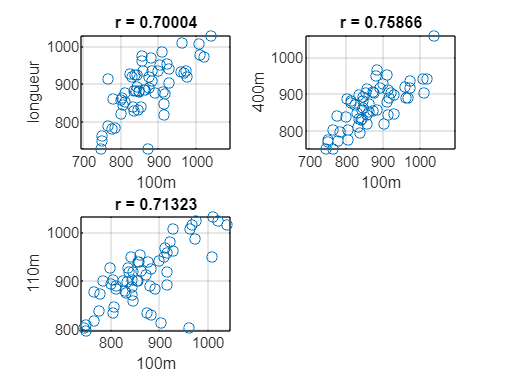

%% représentation
plot_SignificantCorrelation(X_Cor, 0.7, Y, nameVariables, I, 1)

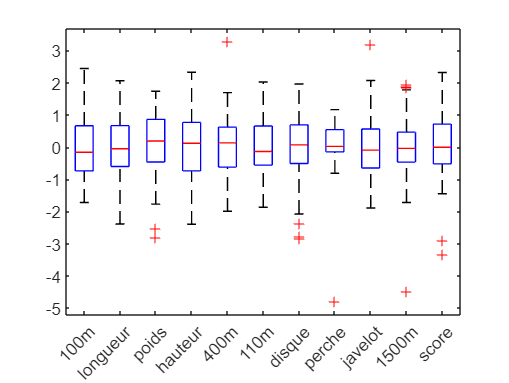

figure(3)
boxplot(X_Normalized, nameVariables)

%% ACP
indexDeletedColumn =1:10;
X_Normalized = X_Normalized(:,indexDeletedColumn);
X_Cor = X_Cor(indexDeletedColumn,indexDeletedColumn); 
Y = Y(:, indexDeletedColumn)

Y =          963        1010         851         850         889        1007         882        1051         918         715
        1040        1030         760         813        1060        1015         733         972         793         829
         929         940         834         878         897        1007         811         941         830         701
        1020         972         755         840         943        1023         767         849         791         735
         801         859         796         822         886         894         854         910        1028         841
         838         925         797         963         794         920         801        1035         796         735
         968         930         780         794         889        1016         895         849         773         670
         973         937         820         758         918         986         874         849         747         699
         858         935    

x_var = var(Y, 1);

% vecteur propres et val propres
[L,B] = eig(X_Cor);
lambda = diag(B);
[lambda, index] = sort(lambda,1,'descend');
V = L(:,index);


%normalisation
M = eye(10); % car on travaille avec X tilde
%beta = ones(1, 10);
%for i=1:10
    %beta(i) = sqrt(x_var(i)/(V(:,i)'*V(:,i)));
    %V(:,i) = V(:,i)*beta(i); % axes principaux
    %(1/x_var(i))*(V(:,i)'*V(:,i)) % verification = 1
%end

% facteurs principaux



% composantes principales
X_Centered = X_Centered(:,indexDeletedColumn); 
C = X_Normalized*V

C =    -3.2156    2.8244    0.4941   -0.0812   -0.2508   -0.6200   -0.1824   -0.1078   -0.5740    0.1287
   -4.9862   -1.0251    0.7545   -0.6276    0.7897   -0.4536    0.1216   -0.1924    0.5250    0.0281
   -2.3190    1.7178    0.0802    0.0338   -0.6835    0.1158   -0.5579    0.2779    0.1838   -0.0235
   -3.2837   -0.1963    0.4198    0.2310   -0.4761   -0.3646   -0.6275   -0.1714   -0.2351   -0.4107
   -0.3849    2.3510    0.7997   -3.1745    0.3185   -0.3543   -0.1639   -1.1463    0.2535    0.0935
   -0.5096    2.2084   -1.8337   -0.5824   -0.5963    0.8286    0.4630    0.0595   -0.4182   -0.3818
   -1.9685    1.1970    1.3129    1.1930   -0.6117   -0.0079   -0.6926   -0.8098   -0.4941    0.0137
   -2.0780    0.9508    1.9576    0.9880   -0.1738    0.0276   -0.0457   -0.2811   -0.1182    0.0194
   -1.4504    0.1523   -1.0420   -0.7572    0.1348    0.6034    0.3140   -0.5027    0.3370    0.2102
   -2.7841   -0.0429    0.4441    0.6828   -0.8536   -0.6358   -0.8409    1.0999   -0.4


% Vérifications
sum(lambda) % =10

ans = 10.0000

C(:, 1)'*D_W*C(:, 1) % =lambda1 normalement 

ans = 3.2875

C(:, 1)'*D_W*C(:, 2) % =0 normalement 

ans = -8.3267e-17

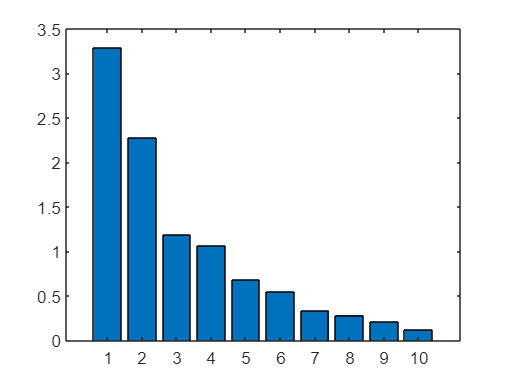

% Interprétations
bar(lambda) % diagramme de coude ou critère de Kaiser (vp>1)

% qualité globale 
% cercle de corrélation (angle petit et distance proche du cercle unité)
